# Asesoria

### Metodos Numericos

#### 2022-2S : 23/11/2022

### ***Duda Laura***

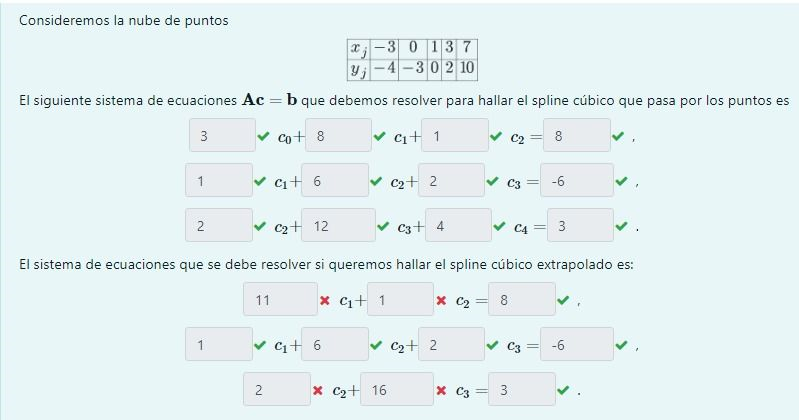

clear
syms c [1 5]                    % Los indices de las constantes c van a quedar desplazadas +1

X = [-3 0 1 3 7];               % Valores de X
Y = [-4 -3 0 2 10];             % Valores de Y

c = [c1 c2 c3 c4 c5];           % Variables c a emplear
h = diff(X);                    % diferencial del intervalo h
a = Y;                          % Equivalencia a_i = y_i


Eq = [];                        % Generación de ecuaciones
for k = 1:3
    LHS = h(k) * c(k) + 2 * (h(k) + h(k + 1)) * c(k +1) + h(k +1) * c(k +2);
    RHS = 3 / h(k +1) * (a(k +2) - a(k +1)) - 3 / h(k) * (a(k +1) - a(k));
    Eq = [Eq; LHS == RHS];
end

Eq1 = Eq(1), Eq2 = Eq(2), Eq3 = Eq(3)

Ahora planteemos las condiciones

Supp = [];

$$Eq1 = 3\,c_{1}+8\,c_{2}+c_{3}=8$$

$$Eq2 = c_{2}+6\,c_{3}+2\,c_{4}=-6$$

$$Eq3 = 2\,c_{3}+12\,c_{4}+4\,c_{5}=3$$

for k = 1:3                     % Condición de Spline Extrapolado
    LHS = (c(k +1) - c(k)) / h(k);
    RHS = (c(k +2) - c(k +1)) / h(k +1);
    Supp = [Supp; LHS == RHS];
end
Supp1 = Supp(1), Supp2 = Supp(3)

Veamos que las condiciones nos permiten eliminar  para la Eq1 y la Eq2 las variables $c_1$ y $c_5$:

C1 = solve(Supp1, c1), C5 = solve(Supp2, c5)

$$Supp1 = \frac{c_{2}}{3}-\frac{c_{1}}{3}=c_{3}-c_{2}$$

$$Supp2 = \frac{c_{4}}{2}-\frac{c_{3}}{2}=\frac{c_{5}}{4}-\frac{c_{4}}{4}$$

Reemplazando en las ecuaciones, resulta:

Eq1 = subs(Eq1, c1, C1); Eq3 = subs(Eq3, c5, C5);

$$C1 = 4\,c_{2}-3\,c_{3}$$

$$C5 = 3\,c_{4}-2\,c_{3}$$

Eq1, Eq2, Eq3

clear


$$Eq1 = 20\,c_{2}-8\,c_{3}=8$$

$$Eq2 = c_{2}+6\,c_{3}+2\,c_{4}=-6$$

$$Eq3 = 24\,c_{4}-6\,c_{3}=3$$

f = @(t, y) 1 + (t - y).^2;
a = 3; b = 6; ya = 2.5; h = .15; M = (b - a) / h;

[T, Y] = milne(f, a, b, ya, M);
Z = [T, Y];
Z(1:5, :)
Y(T == 4.8)

clear


ans =     3.0000    2.5000
    3.1500    2.6848
    3.3000    2.8650
    3.4500    3.0416
    3.6000    3.2155


F = @(x, U) [U(2), cos(U(2)) - exp(-x .* U(1))];

ans = 4.5371

a = -4; b = -1; h = 1/5; M = (b - a) / h;
Za = [-3 -2];

[~, Z] = rks4(F, a, b, Za, M);

Error = -12 - Z(end, 1), Z(end, 1)
Za = [-3 1];

[~, Z] = rks4(F, a, b, Za, M);


Error = 0.3717

ans = -12.3717

Error = -12 - Z(end, 1), Z(end, 1)
Za = [-3 -1];

[T, Z] = rks4(F, a, b, Za, M);


Error = -12.6516

ans = 0.6516

Error = -12 - Z(end, 1), Z(end, 1)

clear

% Límites en x y

Error = -9.6126

ans = -2.3874

a = -1; b = 1; h = 2/3; c = 1; d = 2; k = 1/3;
% Crear los numeros de puntos en x y
N = 1+(b-a)/h; M = 1+(d- c)/k;

% Crear conjunto de puntos
x = linspace(a,b,N)
y = linspace(c,d,M)
[X,Y] = meshgrid(x,y)
% Crear funciones
j = @(x,y) x.^2.*y+x.*y.^2;

x =    -1.0000   -0.3333    0.3333    1.0000


g = @(x,y) 2*(x+y);

y =     1.0000    1.3333    1.6667    2.0000


f1 = @(x) j(x,c);

X =    -1.0000   -0.3333    0.3333    1.0000
   -1.0000   -0.3333    0.3333    1.0000
   -1.0000   -0.3333    0.3333    1.0000
   -1.0000   -0.3333    0.3333    1.0000


Y =     1.0000    1.0000    1.0000    1.0000
    1.3333    1.3333    1.3333    1.3333
    1.6667    1.6667    1.6667    1.6667
    2.0000    2.0000    2.0000    2.0000


f2 = @(y) j(b,y);
f3 = @(x) j(x,d);
f4 = @(y) j(a,y);

U = poisson(g,f1,f2,f3,f4,a,b,c,d,N,M)

clear
syms x y W A
syms w [1 4]


U =          0   -0.2222    0.4444    2.0000
   -0.4444   -0.4444    0.7407    3.1111
   -1.1111   -0.7407    1.1111    4.4444
   -2.0000   -1.1111    1.5556    6.0000


k = 1/5; h = 1/4; X = 3:h:15/4; Y = 1:k:9/5;

LHS(W, w1, w2, w3, w4) = 1/h^2 * (w1 - 2*W + w2) + 1/k^2 * (w3 - 2*W + w4);
RHS(x, y) = cos(x.*y);

Eq(W, w1, w2, w3, w4, x, y) = LHS(W, w1, w2, w3, w4) == RHS(x, y)
EqA = Eq(A, .9602, .3621, .9999, .1313, X(1 + 2), Y(1 + 3))
A = vpa(solve(EqA), 6)

clear

g = @(x, y) x ./ y + y ./ x;

$$Eq(W, w1, w2, w3, w4, x, y) = 16\,w_{1}-82\,W+16\,w_{2}+25\,w_{3}+25\,w_{4}=\cos\left(x\,y\right)$$

f1 = @(x) x.*log(x);

$$EqA = \frac{30898}{625}-82\,A=\cos\left(\frac{28}{5}\right)$$

f2 = @(y) 2*y .* log(2*y);

$$A = 0.59343$$

f3 = @(x) x .* log(4 * x.^2);
f4 = @(y) y.*log(y);

m = 10; n = 5;

help poisson
U = poisson(g, f1, f2, f3, f4, 1, 2, 1, 2, m, n)
Z = U'
U(4, 8), Z(8, 4)

### Envio Max - Revisión

`Punto 1.`` Problema de Valor en la frontera `

Primeramente revisemos el intervalo en consideración, veamos que el problema de frontera se afronta en pasos de $X=\left\lbrack x_0 ,\ldotp \ldotp \ldotp ,x_n \right\rbrack$, con lo que las condiciones centradas se aplican directamente en $X_{\textrm{iterado}} =\left\lbrack a,x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_{n-1} ,b\right\rbrack$, vemos que los valores de interés son los internos, así que: $i=1,\ldotp \ldotp ,M-1$, así: $h=1/4\;\to \;M=16$, $\therefore i=1,\ldotp \ldotp \ldotp ,15$

Por otro lado verifiquemos los valores de los coeficientes.

clear
syms A B C W real
syms w [1 2] real

  poisson.m  -- Resuelve el problema de Poisson u_{xx} + u_{yy} = g(x,y)
  en [a,b] x [c,d], usando el metodo de diferencias finitas de cinco puntos
  g funcion creada con @
  f1 es la condicion de frontera abajo (en y=c) funcion creada con @
  f2 es la condicion de frontera derecha (en x=b) funcion creada con @
  f3 es la condicion de frontera arriba (en y=d) funcion creada con @
  f4 es la condicion de frontera izquierda (en x=a) funcion creada con @
  Las funciones f1, f2, f3 y f4 se ingresan como cadenas de carateres
  m es el numero de puntos sobre el eje x
  n es el numero de puntos sobre el eje y



syms x y real

U =          0    0.1171    0.2453    0.3836    0.5312    0.6873    0.8514    1.0229    1.2013    1.3863
    0.2789    0.4564    0.6478    0.8517    1.0673    1.2934    1.5295    1.7748    2.0287    2.2907
    0.6082    0.8516    1.1116    1.3867    1.6757    1.9775    2.2911    2.6159    2.9510    3.2958
    0.9793    1.2931    1.6264    1.9773    2.3444    2.7264    3.1224    3.5313    3.9523    4.3847
    1.3863    1.7745    2.1849    2.6155    3.0647    3.5310    4.0132    4.5103    5.0212    5.5452


Z =          0    0.2789    0.6082    0.9793    1.3863
    0.1171    0.4564    0.8516    1.2931    1.7745
    0.2453    0.6478    1.1116    1.6264    2.1849
    0.3836    0.8517    1.3867    1.9773    2.6155
    0.5312    1.0673    1.6757    2.3444    3.0647
    0.6873    1.2934    1.9775    2.7264    3.5310
    0.8514    1.5295    2.2911    3.1224    4.0132
    1.0229    1.7748    2.6159    3.5313    4.5103
    1.2013    2.0287    2.9510    3.9523    5.0212
    1.3863    2.2907    3.2958    4.3847    5.5452


h = 1/4;

ans = 3.5313

ans = 3.5313

LHS =  (w1 - 2*W + w2) / h^2 - sin(x) * (w1 - w2) / (2*h) - cos(x) * W;
RHS = atan(3*x);
collect(LHS == RHS, [w1, w2, W])

Estos son los coeficientes que acompañan las variables respectivamente.

`Punto 2. ``Empleamos Milne`

Ingresa en el método: `(Casualmente tengo la función definida)`

clear

f = @(t, y) 2./t .*y + t.^2 .* exp(t);
a = 1; b = 2; M = (b - a) / .05;

[T, M] = milne(f, a, b, 0, M);

Valor = M(T == 1.15), Valor = M(T == 1.35), Valor = M(T == 1.55)
Valor = M(T == 1.85), Valor = M(T == 1.95)

$$ans = \left(16-2\,\sin\left(x\right)\right)\,w_{1}+\left(2\,\sin\left(x\right)+16\right)\,w_{2}+\left(-\cos\left(x\right)-32\right)\,W=\mathrm{atan}\left(3\,x\right)$$

`Punto 3. ``Condiciones de Existencia y Unicidad de PVF`

Este ejercicio lo hicimos durante el repaso, consiste en verificar las condiciones de existencia y unicidad del PVF, para hallar el intervalo basta con una intersección entre los intervalos de las primeras 2 condiciones, y la cota M para la segunda parte es homologa a como se halla en las condiciones de Lipschitz.

`Punto 4. ``Ecuación de segundo orden`

Veamos que las condiciones presentadas solo comentan que se necesita conocer el valor de $y\left(6\right)$:

clear

F = @(t, Y) [Y(2), exp(t/3) + Y(1)/25 - 6*Y(2)];
a = 0; b = 6; h = .5; M = (b - a)/h; Ya = [1 .28];

[T, Y] = rks4(F, a, b, Ya, M);
Y(T == 6, :)

El primer valor corresponde al desplazamiento y el segundo a la velocidad que toma en el tiempo.

`Punto 5.`` Aproximación de un PVF.`

Este ejecicio lo hice en una asesoria, aquí arriba en el cuaderno está desarrollado, este consta en resolver cada uno de los PVI's, y comparar en cada uno cual se acerca mejor al PVF, *un buen criterio es verificar solo la aproximación final de lo PVI's y compararlo con la condición del PVF del valor que debe tomar*

`Punto 6. ``Problema de Poisson`

Verificar que se consideren las condiciones de frontera correctamente e ingresar al método

clear

Valor = 0.5798

Valor = 2.0737

Valor = 4.7857

Valor = 12.4611

Valor = 16.3861

help poisson
f1 = @(x) x.^3; f2 = @(y) 1 + 0*y;
f3 = @(x) x.^3; f4 = @(y) 0 + 0*y;

Si ingresan constantes en las funciones sin la variable en cuestión, vamos a presentar errores.

g = @(x, y) y;

a = 0; b = 1; c = 0; d = 1;
h = 1/4; M = (b - a)/h; N = M;

U = poisson(g, f1, f2, f3, f4, a, b, c, d, M +1, N +1)

La notación que seguimos es: $U\left(\textrm{pasos}\;\textrm{en}\;Y,\textrm{pasos}\;\textrm{en}\;X\right)\to U\left(Y_0 +1\;\textrm{paso},X_0 +2\;\textrm{pasos}\right)$

U(1 + 1, 1 + 2)

ans =     3.1512    7.0476


`Punto 7. ``Problema Poisson`

La primera parte es completamente homologa a la desarrollada en el punto 1, por lo que obviaré explicar.

clear
syms w [1 4]
syms x y A W real

  poisson.m  -- Resuelve el problema de Poisson u_{xx} + u_{yy} = g(x,y)
  en [a,b] x [c,d], usando el metodo de diferencias finitas de cinco puntos
  g funcion creada con @
  f1 es la condicion de frontera abajo (en y=c) funcion creada con @
  f2 es la condicion de frontera derecha (en x=b) funcion creada con @
  f3 es la condicion de frontera arriba (en y=d) funcion creada con @
  f4 es la condicion de frontera izquierda (en x=a) funcion creada con @
  Las funciones f1, f2, f3 y f4 se ingresan como cadenas de carateres
  m es el numero de puntos sobre el eje x
  n es el numero de puntos sobre el eje y




h = 1/4; k = 1/5; a = 3; b = 15/4; c = 1; d = 9/5;

LHS(W, w1, w2, w3, w4) = 1/h^2 *(w1 - 2*W + w2) + 1/k^2 *(w3 - 2*W + w4);
RHS(x, y) = sin(x*y);

Eq(W, w1, w2, w3, w4, x, y) = LHS(W, w1, w2, w3, w4) == RHS(x, y)

Finalmente para hallar $A$ la reemplazamos de las ecuaciones de avance

EqA = Eq(A, -.8589, -.5338, -.3007, -.5151, a + 2*h, c + 2*k)

U =          0    0.0156    0.1250    0.4219    1.0000
         0    0.0951    0.2684    0.5684    1.0000
         0    0.1122    0.3008    0.5988    1.0000
         0    0.0840    0.2550    0.5572    1.0000
         0    0.0156    0.1250    0.4219    1.0000


A = vpa(solve(EqA), 3)

`Código punto 2`

function  [T, Y] = milne (f, a, b, ya, M)

ans = 0.2684


% Entrada  - f funcion creada con @
%          - a y b son los extremos izquierdo y derecho
%          - ya es la condicion inicial  y(a)
%          - M es el numero de pasos
% Salida   - E = [T', Y'] donde T es el vector de abscisas y
%            Y es el vector de ordenadas

%  METODOS NUMERICOS: Programas en Matlab
% (c) 2004 por John H. Mathews y Kurtis D. Fink
%  Software complementario acompa�ando al texto:
%  METODOS NUMERICOS con Matlab, Cuarta Edicion
%  ISBN: 0-13-065248-2

$$Eq(W, w1, w2, w3, w4, x, y) = 16\,w_{1}-82\,W+16\,w_{2}+25\,w_{3}+25\,w_{4}=\sin\left(x\,y\right)$$

%  Prentice-Hall Pub. Inc.
%  One Lake Street

$$EqA = -82\,A-\frac{213391}{5000}=\sin\left(\frac{49}{10}\right)$$

%  Upper Saddle River, NJ 07458

$$A = -0.508$$


h = (b - a) / M;
Y = zeros(1, M+1);
T = a:h:b;
Y(1) = ya;

for k = 1:3
    f1 = feval(f, T(k), Y(k));
    f2 = feval(f, T(k) + 2/3 * h, Y(k) + 2/3*h * f1);
    Y(k + 1) = Y(k) + h/4 * (f1 + 3*f2);
end

for  j = 4:M
    f1 = feval(f, T(j), Y(j));
    f2 = feval(f, T(j -1), Y(j -1));
    f3 = feval(f, T(j -2), Y(j -2));
    Y(j+1) = Y(j-3) + 4/3 * h * (2 * f1 - f2 + 2*f3);
end

T = T'; Y = Y';

end